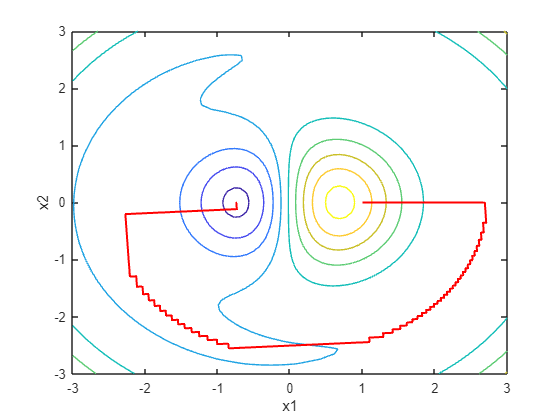

clear all;
close all;
syms x1 x2

eps = 1e-6;
P1=[1, 0]; 
P2=[2, 0];

f(x1, x2) =  0.3*x1+0.1*x2+(-3.5+0.5*x1^2+0.5*x2^2)^2+100*x1 * exp(-x1^2 - x2^2);

n_max = 100;
step = 0;

[route, rozwiazanie] = najwiekszy_spadek(f, eps, P1, n_max, step);

syms x1 x2
fcontour(f(x1, x2), [-3 3])
hold on
plot(route(:, 1), route(:, 2), 'r', 'linewidth', 1.5)
hold off
xlabel("x1")
ylabel("x2")

disp("Przybliżone minimum = " + num2str(rozwiazanie(1)) + ", " + num2str(rozwiazanie(2)))

Przybliżone minimum = -0.7373, -0.0012708


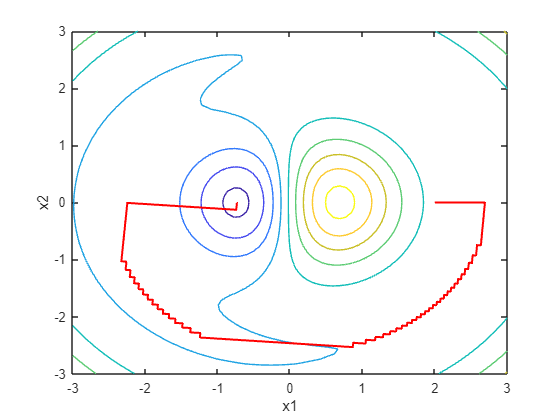


[route, rozwiazanie] = najwiekszy_spadek(f, eps, P2, n_max, step);

syms x1 x2
fcontour(f(x1, x2), [-3 3])
hold on
plot(route(:, 1), route(:, 2), 'r', 'linewidth', 1.5)
hold off
xlabel("x1")
ylabel("x2")

disp("Przybliżone minimum = " + num2str(rozwiazanie(1)) + ", " + num2str(rozwiazanie(2)))

Przybliżone minimum = -0.73726, -0.0012675


function [route, result] = najwiekszy_spadek(f,eps,x0,nmax,step)
syms x1 x2 lambda
i = 0;
x = x0;
route = [x];
result = x;
grad = gradient(f, [x1, x2]);
while i <= nmax
    if step == 0
        gradx = double(grad(x(1), x(2)));
        h(lambda)= f(x(1)+lambda*gradx(1),x(2)+lambda*gradx(2));
        l0 = fminsearch(h, 0);
        x_new = x + gradx' * l0;
    else
        gradx = double(grad(x(1), x(2)));
        h(lambda)= f(x(1)+lambda*gradx(1),x(2)+lambda*gradx(2));
        l0 = fminsearch(h, 0);
        if l0 >=0
            x_new = x + (gradx'/norm(gradx)) * step;
        else
            x_new = x - (gradx'/norm(gradx)) * step;
        end
    end
    warunek = norm(x_new - x)^2;
    if warunek < eps
        result = x_new;
        return
    end
    route = [route; x_new];
    x = x_new;
    i = i+1;
end
result = x_new;
return
end